clear;
clc;
close all;

%% ============================================================
% CAN LOG ANALYZER
%
% Input:
%       Idle.txt
%       RPM_naik.txt
%
% IMPORTANT:
%       DLC is now stored explicitly.
%
%       Same CAN ID with different DLC is treated as a
%       different message variant.
%
% Example:
%
%       0x121 DLC 4 -> B1-B4
%       0x121 DLC 6 -> B1-B6
%       0x121 DLC 8 -> B1-B8
%
% =============================================================


%% ============================================================
% FILES
% ============================================================

idleFile = 'Idle.txt';
rpmFile  = 'RPM_naik.txt';


%% ============================================================
% READ CAN LOGS
% ============================================================

idle = readCANLog(idleFile);
rpm  = readCANLog(rpmFile);

fprintf('Idle frames: %d\n', height(idle));

Idle frames: 48479


fprintf('RPM frames : %d\n', height(rpm));

RPM frames : 12402




%% ============================================================
% SHOW ALL CAN IDs
% ============================================================

idleIDs = unique(idle.ID);
rpmIDs  = unique(rpm.ID);

fprintf('\n===== IDLE CAN IDs =====\n');


===== IDLE CAN IDs =====



for i = 1:length(idleIDs)
    fprintf('0x%X\n', idleIDs(i));
end

0x11F
0x121
0x21F
0x221
0xCFF3386
0xCFF3387
0xCFF3388
0x12FF0001
0x12FF0100
0x12FFFF00
0x12FFFF02
0x12FFFF03
0x12FFFF20
0x13030000
0x13030001
0x13030002
0x13030003
0x13030020
0x13030030
0x16FF0001
0x16FF0020
0x16FF0100
0x16FF0120
0x16FF0320
0x16FF2000
0x16FF2001
0x16FF2003
0x16FFFF20
0x18FECA00




fprintf('\n===== RPM-UP CAN IDs =====\n');


===== RPM-UP CAN IDs =====



for i = 1:length(rpmIDs)
    fprintf('0x%X\n', rpmIDs(i));
end

0x11F
0x121
0x21F
0x221
0xCFF3386
0xCFF3387
0xCFF3388
0x12FF0001
0x12FF0100
0x12FFFF00
0x12FFFF02
0x12FFFF03
0x12FFFF20
0x13030000
0x13030001
0x13030002
0x13030003
0x13030020
0x13030030
0x16FF0001
0x16FF0003
0x16FF0020
0x16FF0100
0x16FF0120
0x16FF0220
0x16FF0300
0x16FF0320
0x16FF2000
0x16FF2001
0x16FF2002
0x16FF2003
0x16FFFF20
0x18FECA00
0x18FF38F0




%% ============================================================
% SHOW CAN ID + DLC COMBINATIONS
% ============================================================

fprintf('\n============================================================\n');

fprintf('ID + DLC COMBINATIONS - IDLE\n');

ID + DLC COMBINATIONS - IDLE


fprintf('============================================================\n');


idlePairs = unique([idle.ID idle.DLC], 'rows');

for i = 1:size(idlePairs,1)

    fprintf( ...
        'ID = 0x%X   DLC = %d\n', ...
        idlePairs(i,1), ...
        idlePairs(i,2));

end

ID = 0x11F   DLC = 8
ID = 0x121   DLC = 8
ID = 0x21F   DLC = 8
ID = 0x221   DLC = 8
ID = 0xCFF3386   DLC = 8
ID = 0xCFF3387   DLC = 4
ID = 0xCFF3388   DLC = 8
ID = 0x12FF0001   DLC = 3
ID = 0x12FF0001   DLC = 4
ID = 0x12FF0001   DLC = 6
ID = 0x12FF0001   DLC = 7
ID = 0x12FF0001   DLC = 8
ID = 0x12FF0100   DLC = 8
ID = 0x12FFFF00   DLC = 3
ID = 0x12FFFF00   DLC = 4
ID = 0x12FFFF00   DLC = 7
ID = 0x12FFFF00   DLC = 8
ID = 0x12FFFF02   DLC = 3
ID = 0x12FFFF02   DLC = 4
ID = 0x12FFFF02   DLC = 7
ID = 0x12FFFF02   DLC = 8
ID = 0x12FFFF03   DLC = 3
ID = 0x12FFFF03   DLC = 4
ID = 0x12FFFF03   DLC = 7
ID = 0x12FFFF03   DLC = 8
ID = 0x12FFFF20   DLC = 3
ID = 0x12FFFF20   DLC = 4
ID = 0x12FFFF20   DLC = 7
ID = 0x12FFFF20   DLC = 8
ID = 0x13030000   DLC = 8
ID = 0x13030001   DLC = 8
ID = 0x13030002   DLC = 8
ID = 0x13030003   DLC = 8
ID = 0x13030020   DLC = 8
ID = 0x13030030   DLC = 8
ID = 0x16FF0001   DLC = 3
ID = 0x16FF0001   DLC = 4
ID = 0x16FF0001   DLC = 6
ID = 0x16FF0001   DLC = 7
ID = 0x16



fprintf('\n============================================================\n');

fprintf('ID + DLC COMBINATIONS - RPM UP\n');

ID + DLC COMBINATIONS - RPM UP


fprintf('============================================================\n');


rpmPairs = unique([rpm.ID rpm.DLC], 'rows');

for i = 1:size(rpmPairs,1)

    fprintf( ...
        'ID = 0x%X   DLC = %d\n', ...
        rpmPairs(i,1), ...
        rpmPairs(i,2));

end

ID = 0x11F   DLC = 8
ID = 0x121   DLC = 8
ID = 0x21F   DLC = 8
ID = 0x221   DLC = 8
ID = 0xCFF3386   DLC = 8
ID = 0xCFF3387   DLC = 4
ID = 0xCFF3388   DLC = 8
ID = 0x12FF0001   DLC = 3
ID = 0x12FF0001   DLC = 4
ID = 0x12FF0001   DLC = 6
ID = 0x12FF0001   DLC = 7
ID = 0x12FF0001   DLC = 8
ID = 0x12FF0100   DLC = 8
ID = 0x12FFFF00   DLC = 3
ID = 0x12FFFF00   DLC = 4
ID = 0x12FFFF00   DLC = 7
ID = 0x12FFFF00   DLC = 8
ID = 0x12FFFF02   DLC = 3
ID = 0x12FFFF02   DLC = 4
ID = 0x12FFFF02   DLC = 7
ID = 0x12FFFF02   DLC = 8
ID = 0x12FFFF03   DLC = 3
ID = 0x12FFFF03   DLC = 4
ID = 0x12FFFF03   DLC = 7
ID = 0x12FFFF03   DLC = 8
ID = 0x12FFFF20   DLC = 3
ID = 0x12FFFF20   DLC = 4
ID = 0x12FFFF20   DLC = 7
ID = 0x12FFFF20   DLC = 8
ID = 0x13030000   DLC = 8
ID = 0x13030001   DLC = 8
ID = 0x13030002   DLC = 8
ID = 0x13030003   DLC = 8
ID = 0x13030020   DLC = 8
ID = 0x13030030   DLC = 8
ID = 0x16FF0001   DLC = 3
ID = 0x16FF0001   DLC = 4
ID = 0x16FF0001   DLC = 6
ID = 0x16FF0001   DLC = 7
ID = 0x16



%% ============================================================
% SELECT A CAN ID TO INVESTIGATE
% ============================================================

selectedID = hex2dec('16FF0020');


idleID = idle(idle.ID == selectedID, :);
rpmID  = rpm(rpm.ID == selectedID, :);


fprintf('\n============================================================\n');

fprintf('INVESTIGATING CAN ID: 0x%X\n', selectedID);

INVESTIGATING CAN ID: 0x16FF0020


fprintf('============================================================\n');


fprintf('Idle frames: %d\n', height(idleID));

Idle frames: 181


fprintf('RPM frames : %d\n', height(rpmID));

RPM frames : 89



PLOTTING 0x16FF0020 - IDLE
DLCs found: 2 3 4 6 7 8 


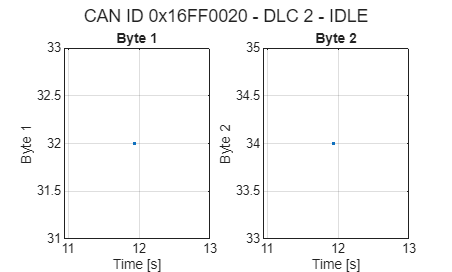

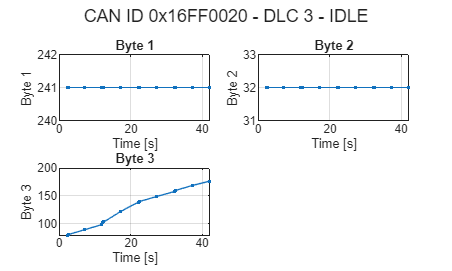

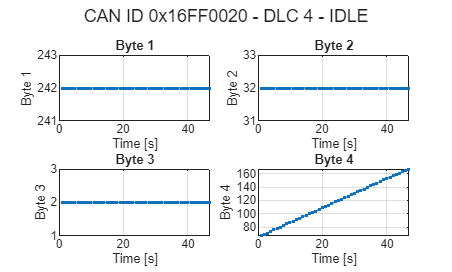

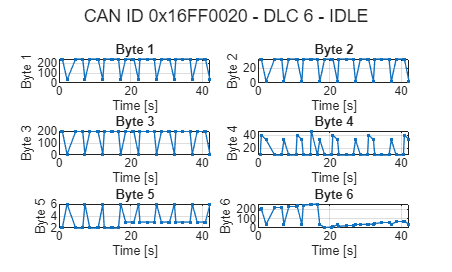

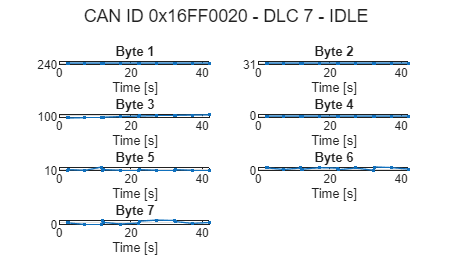

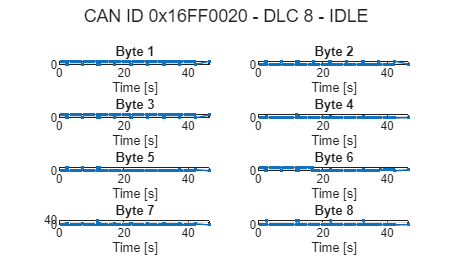



%% ============================================================
% SAFETY CHECK
% ============================================================

if height(idleID) == 0

    warning( ...
        'No frames for CAN ID 0x%X in Idle log.', ...
        selectedID);

end


if height(rpmID) == 0

    warning( ...
        'No frames for CAN ID 0x%X in RPM-Up log.', ...
        selectedID);

end


%% ============================================================
% PLOT SELECTED ID SEPARATED BY DLC
% ============================================================

plotCANByDLC( ...
    idle, ...
    selectedID, ...
    'IDLE');


PLOTTING 0x16FF0020 - RPM UP
DLCs found: 3 4 6 7 8 


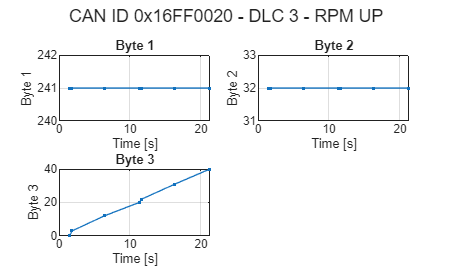

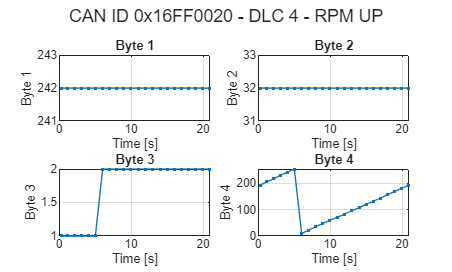

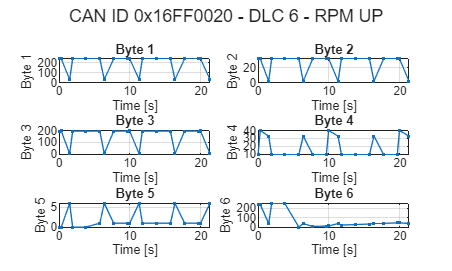

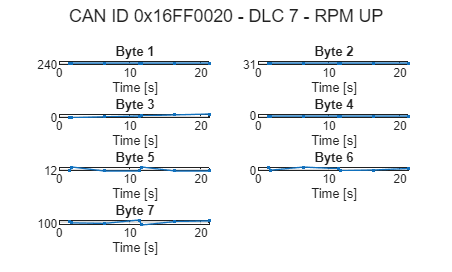

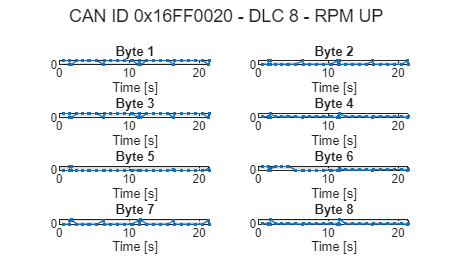



plotCANByDLC( ...
    rpm, ...
    selectedID, ...
    'RPM UP');


0x16FF0020 DLC 2 exists only in one log - skipped comparison.


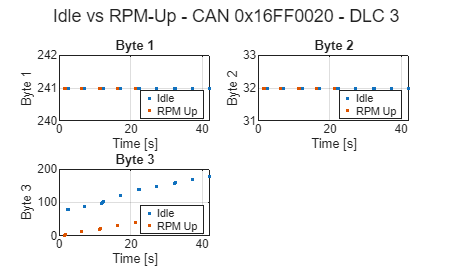

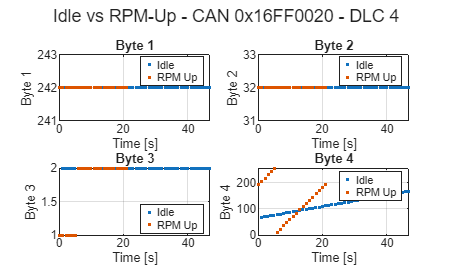

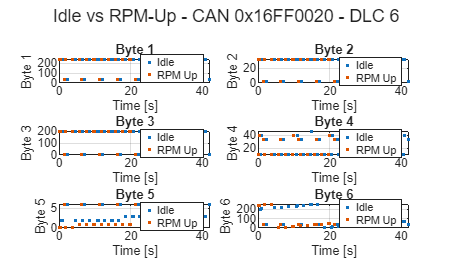

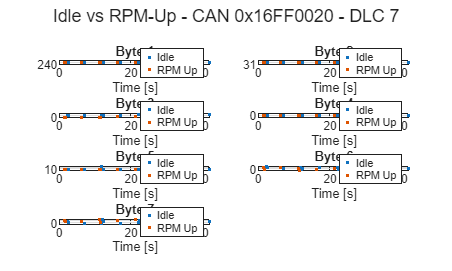

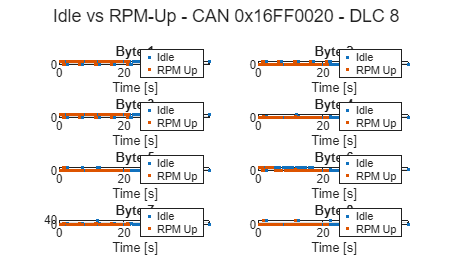



%% ============================================================
% COMPARE MATCHING DLCs
%
% Only DLCs that exist in BOTH logs are compared.
% ============================================================

compareCANByDLC( ...
    idle, ...
    rpm, ...
    selectedID);



%% ============================================================
% BYTE STATISTICS
%
% Statistics are now calculated separately for each DLC.
% ============================================================

fprintf('\n============================================================\n');

fprintf('BYTE STATISTICS - CAN ID 0x%X\n', selectedID);

BYTE STATISTICS - CAN ID 0x16FF0020


fprintf('============================================================\n');



allDLC = unique([ ...
    idleID.DLC; ...
    rpmID.DLC]);


for d = 1:length(allDLC)

    currentDLC = allDLC(d);

    idleDLC = idleID( ...
        idleID.DLC == currentDLC, :);

    rpmDLC = rpmID( ...
        rpmID.DLC == currentDLC, :);


    fprintf('\n------------------------------------------------------------\n');
    fprintf('DLC = %d\n', currentDLC);
    fprintf('------------------------------------------------------------\n');


    fprintf( ...
        '%8s %15s %15s %15s\n', ...
        'Byte', ...
        'Idle Range', ...
        'RPM-Up Range', ...
        'Difference');


    fprintf('%s\n', ...
        repmat('-',1,60));


    for byte = 1:currentDLC

        %% Idle

        if height(idleDLC) > 0

            idleMin = min( ...
                idleDLC.Data(:,byte));

            idleMax = max( ...
                idleDLC.Data(:,byte));

            idleRange = ...
                idleMax - idleMin;

        else

            idleRange = NaN;

        end


        %% RPM Up

        if height(rpmDLC) > 0

            rpmMin = min( ...
                rpmDLC.Data(:,byte));

            rpmMax = max( ...
                rpmDLC.Data(:,byte));

            rpmRange = ...
                rpmMax - rpmMin;

        else

            rpmRange = NaN;

        end


        %% Difference

        difference = ...
            rpmRange - idleRange;


        fprintf( ...
            'B%-7d %15.0f %15.0f %15.0f\n', ...
            byte, ...
            idleRange, ...
            rpmRange, ...
            difference);

    end

end


------------------------------------------------------------


DLC = 2


------------------------------------------------------------


    Byte      Idle Range    RPM-Up Range      Difference


------------------------------------------------------------


B1                     0             NaN             NaN
B2                     0             NaN             NaN



------------------------------------------------------------


DLC = 3


------------------------------------------------------------


    Byte      Idle Range    RPM-Up Range      Difference


------------------------------------------------------------


B1                     0               0               0
B2                     0               0               0
B3                    98              40             -58



------------------------------------------------------------


DLC = 4


------------------------------------------------------------


    Byte      Idle Range    RPM-Up Range      Difference


------------------------------------------------------------


B1                     0               0               0
B2                     0               0               0
B3                     0               1               1
B4                   100             244             144



------------------------------------------------------------


DLC = 6


------------------------------------------------------------


    Byte      Idle Range    RPM-Up Range      Difference


------------------------------------------------------------


B1                   208             208               0
B2                    30              30               0
B3                   190             190               0
B4                    36              30              -6
B5                     4               6               2
B6                   249             250               1



------------------------------------------------------------


DLC = 7


------------------------------------------------------------


    Byte      Idle Range    RPM-Up Range      Difference


------------------------------------------------------------


B1                     0               0               0
B2                     0               0               0
B3                    98              40             -58
B4                     0               0               0
B5                    10               2              -8
B6                   207             179             -28
B7                   220             153             -67



------------------------------------------------------------


DLC = 8


------------------------------------------------------------


    Byte      Idle Range    RPM-Up Range      Difference


------------------------------------------------------------


B1                   208             208               0
B2                   194             192              -2
B3                   242             190             -52
B4                   238             103            -135
B5                   240             245               5
B6                   255             254              -1
B7                    33              13             -20
B8                   248             248               0




%% ============================================================
% 16-BIT SIGNAL TEST
%
% Test adjacent bytes separately for every DLC.
%
% B1:B2
% B2:B3
% ...
%
% Both:
%
% Little Endian
% Big Endian
% ============================================================

fprintf('\n============================================================\n');

fprintf('16-BIT SIGNAL TEST\n');

16-BIT SIGNAL TEST


fprintf('============================================================\n');



for d = 1:length(allDLC)

    currentDLC = allDLC(d);


    % Need at least 2 bytes

    if currentDLC < 2
        continue;
    end


    idleDLC = idleID( ...
        idleID.DLC == currentDLC, :);

    rpmDLC = rpmID( ...
        rpmID.DLC == currentDLC, :);


    fprintf('\n============================================================\n');
    fprintf('DLC = %d\n', currentDLC);
    fprintf('============================================================\n');


    for startByte = 1:(currentDLC-1)

        byteA = startByte;
        byteB = startByte + 1;


        %% ----------------------------------------------------
        % Extract bytes
        % -----------------------------------------------------

        if height(idleDLC) > 0

            idleA = double( ...
                idleDLC.Data(:,byteA));

            idleB = double( ...
                idleDLC.Data(:,byteB));

        end


        if height(rpmDLC) > 0

            rpmA = double( ...
                rpmDLC.Data(:,byteA));

            rpmB = double( ...
                rpmDLC.Data(:,byteB));

        end


        %% ----------------------------------------------------
        % LITTLE ENDIAN
        %
        % B1 + B2*256
        % -----------------------------------------------------

        if height(idleDLC) > 0

            idleLE = ...
                idleA + 256*idleB;

        else

            idleLE = [];

        end


        if height(rpmDLC) > 0

            rpmLE = ...
                rpmA + 256*rpmB;

        else

            rpmLE = [];

        end


        %% ----------------------------------------------------
        % BIG ENDIAN
        %
        % B1*256 + B2
        % -----------------------------------------------------

        if height(idleDLC) > 0

            idleBE = ...
                256*idleA + idleB;

        else

            idleBE = [];

        end


        if height(rpmDLC) > 0

            rpmBE = ...
                256*rpmA + rpmB;

        else

            rpmBE = [];

        end


        %% ----------------------------------------------------
        % PRINT
        % -----------------------------------------------------

        fprintf( ...
            '\nB%d:B%d\n', ...
            byteA, ...
            byteB);


        %% Little Endian

        if ~isempty(idleLE) && ...
           ~isempty(rpmLE)

            idleMedianLE = ...
                median(idleLE);

            rpmMedianLE = ...
                median(rpmLE);


            if idleMedianLE ~= 0

                ratioLE = ...
                    rpmMedianLE / idleMedianLE;

            else

                ratioLE = NaN;

            end


            fprintf( ...
                ' Little Endian: Idle = %.1f | RPM-Up = %.1f | Ratio = %.3f\n', ...
                idleMedianLE, ...
                rpmMedianLE, ...
                ratioLE);

        end


        %% Big Endian

        if ~isempty(idleBE) && ...
           ~isempty(rpmBE)

            idleMedianBE = ...
                median(idleBE);

            rpmMedianBE = ...
                median(rpmBE);


            if idleMedianBE ~= 0

                ratioBE = ...
                    rpmMedianBE / idleMedianBE;

            else

                ratioBE = NaN;

            end


            fprintf( ...
                ' Big Endian   : Idle = %.1f | RPM-Up = %.1f | Ratio = %.3f\n', ...
                idleMedianBE, ...
                rpmMedianBE, ...
                ratioBE);

        end

    end

end

DLC = 2



B1:B2


DLC = 3



B1:B2


 Little Endian: Idle = 8433.0 | RPM-Up = 8433.0 | Ratio = 1.000


 Big Endian   : Idle = 61728.0 | RPM-Up = 61728.0 | Ratio = 1.000



B2:B3


 Little Endian: Idle = 33440.0 | RPM-Up = 5152.0 | Ratio = 0.154


 Big Endian   : Idle = 8322.5 | RPM-Up = 8212.0 | Ratio = 0.987


DLC = 4



B1:B2


 Little Endian: Idle = 8434.0 | RPM-Up = 8434.0 | Ratio = 1.000


 Big Endian   : Idle = 61984.0 | RPM-Up = 61984.0 | Ratio = 1.000



B2:B3


 Little Endian: Idle = 544.0 | RPM-Up = 544.0 | Ratio = 1.000


 Big Endian   : Idle = 8194.0 | RPM-Up = 8194.0 | Ratio = 1.000



B3:B4


 Little Endian: Idle = 30210.0 | RPM-Up = 35330.0 | Ratio = 1.169


 Big Endian   : Idle = 630.0 | RPM-Up = 577.0 | Ratio = 0.916


DLC = 6



B1:B2


 Little Endian: Idle = 8432.0 | RPM-Up = 8432.0 | Ratio = 1.000


 Big Endian   : Idle = 61472.0 | RPM-Up = 61472.0 | Ratio = 1.000



B2:B3


 Little Endian: Idle = 49952.0 | RPM-Up = 49952.0 | Ratio = 1.000


 Big Endian   : Idle = 8387.0 | RPM-Up = 8387.0 | Ratio = 1.000



B3:B4


 Little Endian: Idle = 2755.0 | RPM-Up = 2755.0 | Ratio = 1.000


 Big Endian   : Idle = 49930.0 | RPM-Up = 49930.0 | Ratio = 1.000



B4:B5


 Little Endian: Idle = 778.0 | RPM-Up = 266.0 | Ratio = 0.342


 Big Endian   : Idle = 2563.0 | RPM-Up = 2561.0 | Ratio = 0.999



B5:B6


 Little Endian: Idle = 10755.0 | RPM-Up = 9734.0 | Ratio = 0.905


 Big Endian   : Idle = 803.0 | RPM-Up = 283.0 | Ratio = 0.352


DLC = 7



B1:B2


 Little Endian: Idle = 8433.0 | RPM-Up = 8433.0 | Ratio = 1.000


 Big Endian   : Idle = 61728.0 | RPM-Up = 61728.0 | Ratio = 1.000



B2:B3


 Little Endian: Idle = 33440.0 | RPM-Up = 5152.0 | Ratio = 0.154


 Big Endian   : Idle = 8322.5 | RPM-Up = 8212.0 | Ratio = 0.987



B3:B4


 Little Endian: Idle = 130.5 | RPM-Up = 20.0 | Ratio = 0.153


 Big Endian   : Idle = 33408.0 | RPM-Up = 5120.0 | Ratio = 0.153



B4:B5


 Little Endian: Idle = 3072.0 | RPM-Up = 3072.0 | Ratio = 1.000


 Big Endian   : Idle = 12.0 | RPM-Up = 12.0 | Ratio = 1.000



B5:B6


 Little Endian: Idle = 47116.0 | RPM-Up = 30476.0 | Ratio = 0.647


 Big Endian   : Idle = 3281.5 | RPM-Up = 3267.0 | Ratio = 0.996



B6:B7


 Little Endian: Idle = 30500.5 | RPM-Up = 47922.0 | Ratio = 1.571


 Big Endian   : Idle = 47272.5 | RPM-Up = 30699.0 | Ratio = 0.649


DLC = 8



B1:B2


 Little Endian: Idle = 8432.0 | RPM-Up = 8432.0 | Ratio = 1.000


 Big Endian   : Idle = 61472.0 | RPM-Up = 61472.0 | Ratio = 1.000



B2:B3


 Little Endian: Idle = 50208.0 | RPM-Up = 50208.0 | Ratio = 1.000


 Big Endian   : Idle = 8388.0 | RPM-Up = 8388.0 | Ratio = 1.000



B3:B4


 Little Endian: Idle = 5316.0 | RPM-Up = 5316.0 | Ratio = 1.000


 Big Endian   : Idle = 50196.0 | RPM-Up = 50196.0 | Ratio = 1.000



B4:B5


 Little Endian: Idle = 788.0 | RPM-Up = 276.0 | Ratio = 0.350


 Big Endian   : Idle = 5122.0 | RPM-Up = 5121.0 | Ratio = 1.000



B5:B6


 Little Endian: Idle = 13571.0 | RPM-Up = 7041.0 | Ratio = 0.519


 Big Endian   : Idle = 805.0 | RPM-Up = 286.0 | Ratio = 0.355



B6:B7


 Little Endian: Idle = 212.0 | RPM-Up = 46.0 | Ratio = 0.217


 Big Endian   : Idle = 13568.0 | RPM-Up = 7040.0 | Ratio = 0.519



B7:B8


 Little Endian: Idle = 3840.0 | RPM-Up = 3840.0 | Ratio = 1.000


 Big Endian   : Idle = 15.0 | RPM-Up = 15.0 | Ratio = 1.000




%% ============================================================
% KNOWN RPM REFERENCE
% ============================================================

idleRPM = 1042;

boomRPM_low  = 1600;
boomRPM_high = 1700;


expectedRatioLow = ...
    boomRPM_low / idleRPM;

expectedRatioHigh = ...
    boomRPM_high / idleRPM;


fprintf('\n============================================================\n');

fprintf('KNOWN RPM REFERENCE\n');

KNOWN RPM REFERENCE


fprintf('============================================================\n');


fprintf( ...
    'Idle RPM          = %.0f RPM\n', ...
    idleRPM);

Idle RPM          = 1042 RPM



fprintf( ...
    'Boom-up RPM       = %.0f - %.0f RPM\n', ...
    boomRPM_low, ...
    boomRPM_high);

Boom-up RPM       = 1600 - 1700 RPM



fprintf( ...
    'Expected ratio    = %.3f - %.3f\n', ...
    expectedRatioLow, ...
    expectedRatioHigh);

Expected ratio    = 1.536 - 1.631




%% ============================================================
% FINISHED
% ============================================================

fprintf('\n============================================================\n');

fprintf('ANALYSIS COMPLETE\n');

ANALYSIS COMPLETE


fprintf('============================================================\n');




%% ============================================================
% FUNCTION:
% PLOT CAN ID SEPARATED BY DLC
% ============================================================

function plotCANByDLC(T, selectedID, logName)


    %% --------------------------------------------------------
    % Select CAN ID
    % ---------------------------------------------------------

    selected = ...
        T(T.ID == selectedID, :);


    if isempty(selected)

        fprintf( ...
            'No frames for 0x%X in %s.\n', ...
            selectedID, ...
            logName);

        return;

    end


    %% --------------------------------------------------------
    % Find DLCs
    % ---------------------------------------------------------

    dlcs = unique(selected.DLC);


    fprintf('\n============================================================\n');
    fprintf('PLOTTING 0x%X - %s\n', ...
        selectedID, logName);

    fprintf('DLCs found: ');

    fprintf('%d ', dlcs);

    fprintf('\n');


    %% --------------------------------------------------------
    % Plot each DLC separately
    % ---------------------------------------------------------

    for d = 1:length(dlcs)


        currentDLC = dlcs(d);


        subset = selected( ...
            selected.DLC == currentDLC, :);


        figure;


        %% ----------------------------------------------------
        % Determine subplot layout
        % -----------------------------------------------------

        rows = ceil(currentDLC / 2);

        cols = 2;


        %% ----------------------------------------------------
        % Plot each byte
        % -----------------------------------------------------

        for byte = 1:currentDLC


            subplot(rows, cols, byte);


            plot( ...
                subset.Time, ...
                subset.Data(:,byte), ...
                '.-' ...
            );


            grid on;


            xlabel('Time [s]');


            ylabel( ...
                sprintf('Byte %d', byte));


            title( ...
                sprintf('Byte %d', byte));


        end


        %% ----------------------------------------------------
        % Figure title
        % -----------------------------------------------------

        sgtitle( ...
            sprintf( ...
                'CAN ID 0x%X - DLC %d - %s', ...
                selectedID, ...
                currentDLC, ...
                logName));


    end

end



%% ============================================================
% FUNCTION:
% COMPARE IDLE VS RPM-UP BY DLC
% ============================================================

function compareCANByDLC( ...
    idle, ...
    rpm, ...
    selectedID)


    %% --------------------------------------------------------
    % Select ID
    % ---------------------------------------------------------

    idleID = ...
        idle(idle.ID == selectedID, :);


    rpmID = ...
        rpm(rpm.ID == selectedID, :);


    %% --------------------------------------------------------
    % Find DLCs existing in either log
    % ---------------------------------------------------------

    allDLC = unique([ ...
        idleID.DLC; ...
        rpmID.DLC]);


    %% --------------------------------------------------------
    % Loop through DLC
    % ---------------------------------------------------------

    for d = 1:length(allDLC)


        currentDLC = allDLC(d);


        idleDLC = idleID( ...
            idleID.DLC == currentDLC, :);


        rpmDLC = rpmID( ...
            rpmID.DLC == currentDLC, :);


        %% ----------------------------------------------------
        % If only one condition has this DLC
        % -----------------------------------------------------

        if isempty(idleDLC) || isempty(rpmDLC)

            fprintf( ...
                '\n0x%X DLC %d exists only in one log - skipped comparison.\n', ...
                selectedID, ...
                currentDLC);

            continue;

        end


        %% ----------------------------------------------------
        % Create figure
        % -----------------------------------------------------

        figure;


        rows = ceil(currentDLC / 2);

        cols = 2;


        %% ----------------------------------------------------
        % Plot
        % -----------------------------------------------------

        for byte = 1:currentDLC


            subplot(rows, cols, byte);


            plot( ...
                idleDLC.Time, ...
                idleDLC.Data(:,byte), ...
                '.', ...
                'DisplayName','Idle');


            hold on;


            plot( ...
                rpmDLC.Time, ...
                rpmDLC.Data(:,byte), ...
                '.', ...
                'DisplayName','RPM Up');


            grid on;


            xlabel('Time [s]');


            ylabel( ...
                sprintf('Byte %d', byte));


            title( ...
                sprintf('Byte %d', byte));


            legend('Location','best');


        end


        %% ----------------------------------------------------
        % Title
        % -----------------------------------------------------

        sgtitle( ...
            sprintf( ...
                'Idle vs RPM-Up - CAN 0x%X - DLC %d', ...
                selectedID, ...
                currentDLC));


    end

end



%% ============================================================
% FUNCTION:
% READ CANGAROO TXT
% ============================================================

function T = readCANLog(filename)


    %% --------------------------------------------------------
    % Open file
    % ---------------------------------------------------------

    fid = fopen(filename,'r');


    if fid == -1

        error( ...
            'Cannot open file: %s', ...
            filename);

    end


    %% --------------------------------------------------------
    % Skip header
    % ---------------------------------------------------------

    fgetl(fid);


    %% --------------------------------------------------------
    % Storage
    % ---------------------------------------------------------

    ID = [];

    Time = [];

    DLC = [];

    Data = [];


    %% --------------------------------------------------------
    % Read every line
    % ---------------------------------------------------------

    while ~feof(fid)


        line = fgetl(fid);


        if ~ischar(line)

            continue;

        end


        %% ----------------------------------------------------
        % Timestamp
        % -----------------------------------------------------

        timeToken = regexp( ...
            line, ...
            '\d+:\d+:\d+\s+\d+', ...
            'match', ...
            'once');


        %% ----------------------------------------------------
        % CAN ID
        % -----------------------------------------------------

        idToken = regexp( ...
            line, ...
            '0x[0-9A-Fa-f]+', ...
            'match', ...
            'once');


        %% ----------------------------------------------------
        % Data
        % -----------------------------------------------------

        dataToken = regexp( ...
            line, ...
            '([0-9A-Fa-f]{2}(?:\s+[0-9A-Fa-f]{2})*)\s*$', ...
            'match', ...
            'once');


        %% ----------------------------------------------------
        % Validate
        % -----------------------------------------------------

        if isempty(timeToken) || ...
           isempty(idToken) || ...
           isempty(dataToken)

            continue;

        end


        %% ----------------------------------------------------
        % Convert timestamp
        % -----------------------------------------------------

        timeParts = sscanf( ...
            timeToken, ...
            '%d:%d:%d %d');


        if length(timeParts) < 4

            continue;

        end


        h  = timeParts(1);

        m  = timeParts(2);

        s  = timeParts(3);

        ms = timeParts(4);


        t = ...
            h*3600 + ...
            m*60 + ...
            s + ...
            ms/1000;


        %% ----------------------------------------------------
        % Convert CAN ID
        % -----------------------------------------------------

        canID = ...
            hex2dec(idToken);


        %% ----------------------------------------------------
        % Extract bytes
        % -----------------------------------------------------

        hexBytes = regexp( ...
            dataToken, ...
            '[0-9A-Fa-f]{2}', ...
            'match');


        %% ----------------------------------------------------
        % Determine DLC
        % -----------------------------------------------------

        dlc = length(hexBytes);


        %% ----------------------------------------------------
        % Reject impossible DLC
        % -----------------------------------------------------

        if dlc < 1 || dlc > 8

            continue;

        end


        %% ----------------------------------------------------
        % Store payload
        %
        % Missing bytes are padded with NaN, NOT zero.
        %
        % This is important:
        %
        % NaN = byte doesn't exist
        %
        % 0   = byte exists and its value is zero
        % -----------------------------------------------------

        bytes = NaN(1,8);


        for k = 1:dlc

            bytes(k) = ...
                hex2dec(hexBytes{k});

        end


        %% ----------------------------------------------------
        % Store frame
        % -----------------------------------------------------

        ID(end+1,1) = canID;

        Time(end+1,1) = t;

        DLC(end+1,1) = dlc;

        Data(end+1,:) = bytes;


    end


    %% --------------------------------------------------------
    % Close file
    % ---------------------------------------------------------

    fclose(fid);


    %% --------------------------------------------------------
    % Check
    % ---------------------------------------------------------

    if isempty(ID)

        error( ...
            ['No valid CAN frames were parsed from "%s". ' ...
             'Check the TXT file format.'], ...
            filename);

    end


    %% --------------------------------------------------------
    % Normalize time
    % ---------------------------------------------------------

    Time = ...
        Time - Time(1);


    %% --------------------------------------------------------
    % Create table
    % ---------------------------------------------------------

    T = table( ...
        ID, ...
        Time, ...
        DLC, ...
        Data);

end